% clc; clear; close all;
% 
% % Load the image
% image1 = imread('Trial_Image_1.jpg');
% image2 = imread('Trial_Image_2.jpg');
% 
% % Convert to grayscale
% gray1 = rgb2gray(image1);
% gray2 = rgb2gray(image2);
% 
% % Apply Canny Edge Detection
% edges1 = edge(gray1, 'Canny');
% edges2 = edge(gray2, 'Canny');
% 
% % Display Canny Edge Detected Images
% figure;
% subplot(1, 2, 1);
% imshow(edges1);
% title('Canny Edge Detection - Frame 1');
% 
% subplot(1, 2, 2);
% imshow(edges2);
% title('Canny Edge Detection - Frame 2');
% 
% % Now, you can track changes across frames by comparing the edges
% % Example: Count number of non-zero pixels (edges detected)
% disp('Number of edges detected in Frame 1:');
% disp(nnz(edges1));  % Count non-zero (edge) pixels
% 
% disp('Number of edges detected in Frame 2:');
% disp(nnz(edges2));  % Count non-zero (edge) pixels

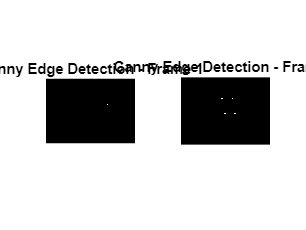

clc; clear; close all;

% Load the image
image1 = imread('Trial_Image_1.jpg');
image2 = imread('Trial_Image_2.jpg');

% Convert to grayscale
gray1 = rgb2gray(image1);
gray2 = rgb2gray(image2);

% Apply Gaussian Blur to reduce noise
blurred1 = imgaussfilt(gray1, 3);  
blurred2 = imgaussfilt(gray2, 3);  

% Apply Canny Edge Detection with thresholds
edges1 = edge(blurred1, 'Canny', [0.1 0.3]);  % [lowThreshold highThreshold]
edges2 = edge(blurred2, 'Canny', [0.1 0.3]);  % Adjust thresholds as needed

% Post-processing: Dilation followed by Erosion to close gaps
se = strel('line', 5, 0);  % Structuring element for horizontal lines
edges1 = imdilate(edges1, se);
edges1 = imerode(edges1, se);

edges2 = imdilate(edges2, se);
edges2 = imerode(edges2, se);

% Display the results
figure;
subplot(1, 2, 1);
imshow(edges1);
title('Canny Edge Detection - Frame 1');

subplot(1, 2, 2);
imshow(edges2);
title('Canny Edge Detection - Frame 2');


% Now, you can track changes across frames by comparing the edges
disp('Number of edges detected in Frame 1:');

Number of edges detected in Frame 1:


disp(nnz(edges1));  % Count non-zero (edge) pixels

        2316




disp('Number of edges detected in Frame 2:');

Number of edges detected in Frame 2:


disp(nnz(edges2));  % Count non-zero (edge) pixels

        2468



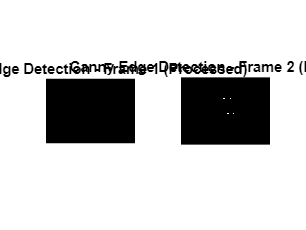

% Median Filter
clc; clear; close all;

% Load the image
image1 = imread('Trial_Image_1.jpg');
image2 = imread('Trial_Image_2.jpg');

% Convert to grayscale
gray1 = rgb2gray(image1);
gray2 = rgb2gray(image2);

% Apply Median Filter to reduce noise (try this instead of Gaussian filter)
filtered1 = medfilt2(gray1, [5 5]);  % Apply 5x5 median filter
filtered2 = medfilt2(gray2, [5 5]);  % Adjust this size if needed

% Apply Canny Edge Detection with adjusted thresholds
edges1 = edge(filtered1, 'Canny', [0.1 0.3]);  % Adjust thresholds as needed
edges2 = edge(filtered2, 'Canny', [0.1 0.3]);  % Adjust thresholds as needed

% Post-processing: Dilation followed by Erosion to close gaps
se = strel('line', 10, 0);  % Larger structuring element for horizontal lines
edges1 = imdilate(edges1, se);
edges1 = imerode(edges1, se);

edges2 = imdilate(edges2, se);
edges2 = imerode(edges2, se);

% Display the results
figure;
subplot(1, 2, 1);
imshow(edges1);
title('Canny Edge Detection - Frame 1 (Processed)');

subplot(1, 2, 2);
imshow(edges2);
title('Canny Edge Detection - Frame 2 (Processed)');


% Now, you can track changes across frames by comparing the edges
disp('Number of edges detected in Frame 1 (after processing):');

Number of edges detected in Frame 1 (after processing):


disp(nnz(edges1));  % Count non-zero (edge) pixels

        2333




disp('Number of edges detected in Frame 2 (after processing):');

Number of edges detected in Frame 2 (after processing):


disp(nnz(edges2));  % Count non-zero (edge) pixels

        2024



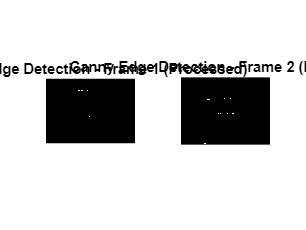

clc; clear; close all;

% Load the image
image1 = imread('Trial_Image_1.jpg');
image2 = imread('Trial_Image_2.jpg');

% Convert to grayscale
gray1 = rgb2gray(image1);
gray2 = rgb2gray(image2);

% Apply Adaptive Histogram Equalization to enhance contrast
adjusted1 = adapthisteq(gray1, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');
adjusted2 = adapthisteq(gray2, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');

% Apply Gaussian Blur for noise reduction (smooth the image)
blurred1 = imgaussfilt(adjusted1, 1);  % Adjust sigma as needed (1 is default)
blurred2 = imgaussfilt(adjusted2, 1);  % Adjust sigma as needed

% Apply Canny Edge Detection with adjusted thresholds
edges1 = edge(blurred1, 'Canny', [0.05 0.17]);  % Lower thresholds to detect thinner edges
edges2 = edge(blurred2, 'Canny', [0.05 0.17]);  % Adjust thresholds as needed

% Post-processing: Erosion followed by Dilation to reduce line thickness and connect edges
se = strel('line', 10, 0);  % Structuring element for horizontal lines
edges1 = imerode(edges1, se);  % Erosion reduces line thickness
edges1 = imdilate(edges1, se); % Dilation to re-connect edges

edges2 = imerode(edges2, se);  % Erosion reduces line thickness
edges2 = imdilate(edges2, se); % Dilation to re-connect edges

% Optionally, apply closing operation to further refine edges
edges1 = imclose(edges1, se);
edges2 = imclose(edges2, se);

% Remove unwanted edges (masking the image)
mask1 = edges1 & (blurred1 > 0.1);  % Apply thresholding on original grayscale for better edge selection
mask2 = edges2 & (blurred2 > 0.1);  % Apply thresholding on original grayscale for better edge selection

% Display the results
figure;
subplot(1, 2, 1);
imshow(mask1);
title('Canny Edge Detection - Frame 1 (Processed)');

subplot(1, 2, 2);
imshow(mask2);
title('Canny Edge Detection - Frame 2 (Processed)');


% Now, you can track changes across frames by comparing the edges
disp('Number of edges detected in Frame 1 (after processing):');

Number of edges detected in Frame 1 (after processing):


disp(nnz(mask1));  % Count non-zero (edge) pixels

        3019




disp('Number of edges detected in Frame 2 (after processing):');

Number of edges detected in Frame 2 (after processing):


disp(nnz(mask2));  % Count non-zero (edge) pixels

        3596



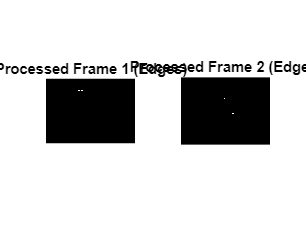

clc; clear; close all;

% Load the image
image1 = imread('Trial_Image_1.jpg');
image2 = imread('Trial_Image_2.jpg');

% Convert to grayscale
gray1 = rgb2gray(image1);
gray2 = rgb2gray(image2);

% Apply Adaptive Histogram Equalization to enhance contrast
adjusted1 = adapthisteq(gray1, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');
adjusted2 = adapthisteq(gray2, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');

% Apply Gaussian Blur for noise reduction (smooth the image)
blurred1 = imgaussfilt(adjusted1, 1);  % Adjust sigma as needed (1 is default)
blurred2 = imgaussfilt(adjusted2, 1);  % Adjust sigma as needed

% Apply Canny Edge Detection with adjusted thresholds
edges1 = edge(blurred1, 'Canny', [0.1 0.2]);  % Adjusted thresholds
edges2 = edge(blurred2, 'Canny', [0.1 0.2]);  % Adjusted thresholds

% Post-processing: Erosion followed by Dilation to reduce line thickness and connect edges
se = strel('line', 20, 0);  % Increase the size of the structuring element for horizontal lines
edges1 = imerode(edges1, se);  % Erosion reduces line thickness
edges1 = imdilate(edges1, se); % Dilation to re-connect edges

edges2 = imerode(edges2, se);  % Erosion reduces line thickness
edges2 = imdilate(edges2, se); % Dilation to re-connect edges

% Apply Closing Operation to further refine edges (close gaps between fragments)
edges1 = imclose(edges1, se);
edges2 = imclose(edges2, se);

% Remove unwanted edges (masking the image)
mask1 = edges1 & (blurred1 > 0.1);  % Apply thresholding on original grayscale for better edge selection
mask2 = edges2 & (blurred2 > 0.1);  % Apply thresholding on original grayscale for better edge selection

% Display the results
figure;
subplot(1, 2, 1);
imshow(mask1);
title('Processed Frame 1 (Edges)');

subplot(1, 2, 2);
imshow(mask2);
title('Processed Frame 2 (Edges)');


% Now, you can track changes across frames by comparing the edges
disp('Number of edges detected in Frame 1 (after processing):');

Number of edges detected in Frame 1 (after processing):


disp(nnz(mask1));  % Count non-zero (edge) pixels

        2285




disp('Number of edges detected in Frame 2 (after processing):');

Number of edges detected in Frame 2 (after processing):


disp(nnz(mask2));  % Count non-zero (edge) pixels

        2111

